# Revised Project Proposal - SYS6014 - Jamie Quintana

This project topic is concerned with crypto currencies (like Bitcoin), and when it might be the best (or optimal) time to buy (i.e. buy currency on a day the price will likely go up vice down). Unlike stocks, crypto currency prices change based on various factors and is tracked everyday.  The focus here is to take the historical data (which is readily available) draw the line say at the end of Dec 31, 2019, and calculate probabilities for each day – Monday-Sunday to determine if one or more days are preferred to buy than another (calculate utility/loss functions for each, which will drive the decision to buy (or not).  Basically – the price can go up or down (i.e. binary) from one day to the next **p =.5**; however, the actual probabilities may be (and most likely are) different depending on the overall data set (summed) or calculated for each day, each month, or determined by some prediction model.

The decision-maker's ***action set*** $A$ : A complete itemization of all the options available to the decision-maker, from which the decision-maker selects a unique choice.

Let ${\mathit{\mathbf{a}}}_{\mathit{\mathbf{d}}}$be a binary control variable that takes a value of **1** if a decision to buy bitcoins occurs on date **d**, and **0 **otherwise. 

Let random variable **x = **($\left.x_{d,\;} x_{d-1,\ldotp \ldotp \ldotp \ldotp \ldotp \;} x_1 \right)$denote the vector of potential probabilites, which the decision maker will encounter and let **a = **($\left.a_{d,\;} a_{d-1,\ldotp \ldotp \ldotp \ldotp \ldotp \;} a_1 \right)$ denote the vector of all decisions taken on givens days which consume a given budject ***B***. For this project, the max budject ***B***  is set at **$5,000**. 

Then $a\cdot x=\sum a_d x_d$  is the realized number of successful purchases (where bitcoin price went up as predicted) per given day.   The goal to maximize in expectation the total number of successful purchase days, which can be expressed as:

$\underset{a}{\textrm{MAX}}$ ***E*** [$a\cdot x$] subject to budget constraint $\sum a_d$ $\le B$

*As a notional way ahead, we can create a senario where the decsion maker has to make **ten purchases** each @ $500 of bitcoins within a 30 day period using the decsion tools in this project. As a comparision, the results of the maximized decsions using the model's data will be compared againt **ten "randomized" purchases** within the defined 30-day perdiod  to compare the performace of the model.  *

***Below is a full list of actions which the decision maker will make... other possible actions can/may be added as the course progresses. ***

  ***Actions*** 

  **No.**  **Description** 

  1  Do not buy bitcoins 

  2  Buy bitcoins without using model data 

  3  Buy bitcoins on Mondays 

  4  Buy bitcoins on Tuesdays 

  5  Buy bitcoins on Wednesdays 

  6  Buy bitcoins on Thursdays 

  7  Buy bitcoins on Fridays 

  8  Buy bitcoins on Saturdays 

  9  Buy bitcoins on Sundays 

  10  Buy bitcoins based on price prediction forecast (next day prediction: up or down)

  11  Buy bitcoins based on (feature extraction) prediction model (next day prediction: up or down)

**Notes:**

**Actions 10 and 11 will require creating classification or machine learning models using neural networks, SVMs, etc. that use the data (perhaps even transformed using filters, tools, feature extractors) to forecast or predict outcomes. **

**Specifically, for Action no.10, I will create a model that uses historical data to predict ****the next day's price value**** - and then compare the predicted values over actual values for a period of time (say two weeks).  For Action 11 (which is vasty more complicated), I will use either daily or hourly data (per day) to mine for patterns within the data to predict the next day's outcome (i.e. price goes up or price goes down).  Again, using a period of two weeks (min) to determine models accuracy based on actual versus predicted.  Leaving no.11 as optional for now - may be too much to undertake... Time will tell, but I'm eager to try. **

The ***state space*** or *sample space *$X$ : The space from which observation data are drawn. 

**Direct data will not be used. Instead, the sample space for each action will be derived (i.e. calculated) from the full set of data as described in the next section. Full data set contains 6 columns of numerical 1845 data points (i.e. from 12/1/2014 to 12/31/2019) with column titles - Open, High, Low, Close, Volume BTC, and Volume USD. **

Some description of the ***data generating process***. This might take the form of a *statistical model* describing the statistical properties of random variables ${}X_1$,${}X_2$,…,${}X_n$∈X.

**For each Random variable **${}X_i$**,~ 263 data points will be parsed from the entire data set for each day of the week **

**Then, each group of 263 ~ data points  will be divided into two groups: first group summing all times the bitcoin price when up, and second for all times the prices went  down. Then their associated **$L\left(\theta ,a\right)$**'s will be calculated for each day.**

**Note: for any days where price neither went up nor down resulting in a zero sum gain, I'm thinking to create a third group called "no gain" to account for those instances.  If frequency is determined to be inconsequntial, that is, rarley occuring, I will combine the days with no gains in with the "good call" group vice "bad call" group.   **

The ***parameter space*** $\Theta$ : The parameter space is then the set of all possible values of θ and ${}{\sigma }^2$: $\Theta =R\times \left\lbrack 0,\infty \right)$.

**For this project, the complete parameter space containing all the possible states will be contained within **$\Theta =\left\lbrack 0,1\right)$**Although, most of the observered θ's with be roughly in the ~.5 range with hopes that one of the two pre-processing predictive models will obtain **$L\left(\theta ,a\right)$**'s with **$\theta^{\prime } s\;$**above the .5 value nearing .6 or .7 if acheivable. **

**Regarding the unknowns, I'm considering the option of determining the average gain or loss on a particular day of the week to be used as a scale-type factor associated with the "value" of a price going up or down for a given day of the week. Meaning,  unlike the sample chart further down where all the perceived values are the same for each day of the week, they will be scaled - or adjusted based on the calculated average... I'll assume for now they will not be all the same and some variance will be determined. **

A description of the decision-maker's ***prior beliefs ***$\pi \left(\theta \right)$*. *These beliefs describe the information or beliefs the decision-maker has about the values of the unobserved parameters before collecting data. These beliefs can generally be represented as a probability distribution over the parameter space $\Theta$.

**I think most people (i.e. decision makers) believe there is no real, consistent, reliable way to determine when is the best time to make a purchase - almost regardless of what it is (assuming whatever stock or asset being purchased is optional and not manatory). So, in the case of this project, any prior belief that there exists some method or previous way to determine if price will go up or down is off the table. Meaning, project will assume the probablity is 50/50 (p = .5) one way or another and no external factors or variables outside the data set will be used or referenced.  So without trying to quantify the amount of price increases or decreases, the simple answer to the question of "will bit coins go up or down the next day" is binary. That is, yes or no. **

The relevant ***payoffs*** that could result from the action. Payoffs will be a function of the selected action a, and the realized value of an uncertain random variable.

**In my proposed model, I can setup multiple tables with different values associated with each action selection based on three different risk profiles (i.e. *****Risk Neutral, Risk Averse, and Risk Seeking*****).  ****Table below is notionally Risk Neutral****. Addtional tables can be generated based on actual amount of investment (i.e. values adjusted non linearly as quantity of the bitcoin purchase increases - perhaps, $100, $1000, and $10000 options.  **

**Note: the **$\pi \left(\theta \right)$** for actions 1and 2 is assumed. and the **${\left(\theta \right)}^{\prime } s\;$**for actions 3 through 11 are fictional (placeholders for the real values to be calculated). Also, instead a a negative perpective of using a loss function, I plan to use a positive payoff perspective - seeking higher values being the best choice to drive the decision. Also, as noted above, I will most likely add a thrid state of nature to capture the "no gain" result which may occur (regardless of the low frequency of occurence).  **

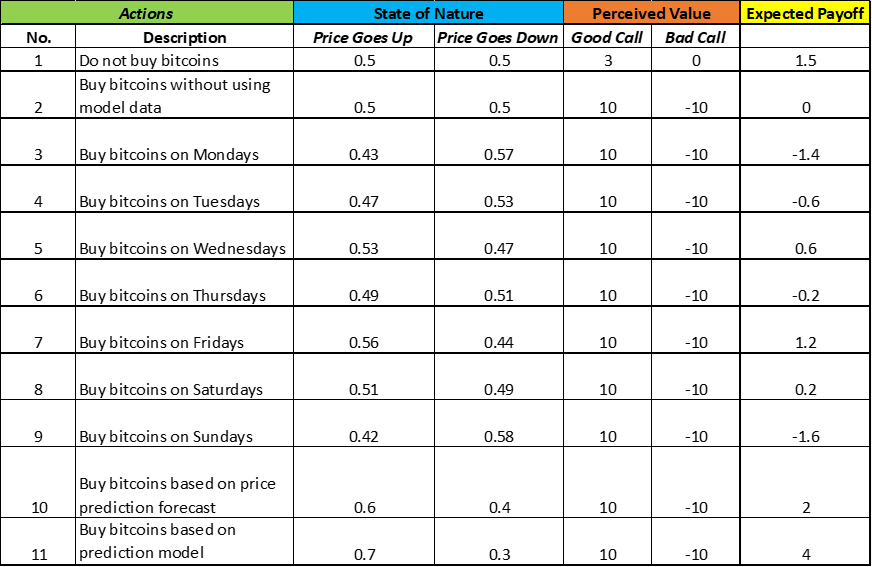

**Data: **In addition to adding this formalism, you must identify the source of data you will be using.

URL for full data source (updated hourly, daily): [http://www.cryptodatadownload.com/data/coinbase/](http://www.cryptodatadownload.com/data/coinbase/)

***End of revised project proposal - below is the fun stuff! ***

Sample of MATAB code below to show how action no.10 could possibly work: 

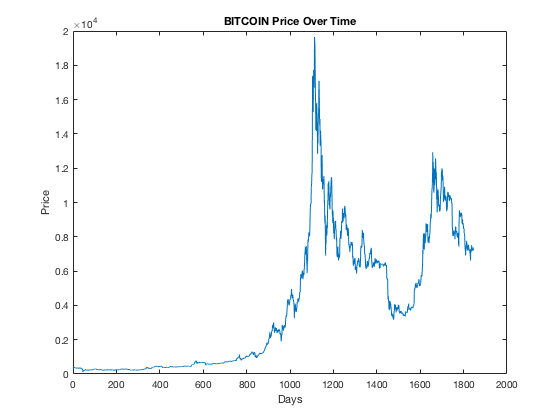

clear all;
close all;
rng(12345);
input = csvread('2020-02-18_BTC-data.csv');
data = input;
data = data';
data(1846)=data(1845);
figure
plot(data)
xlabel("Days")
ylabel("Price")
title("BITCOIN Price Over Time")

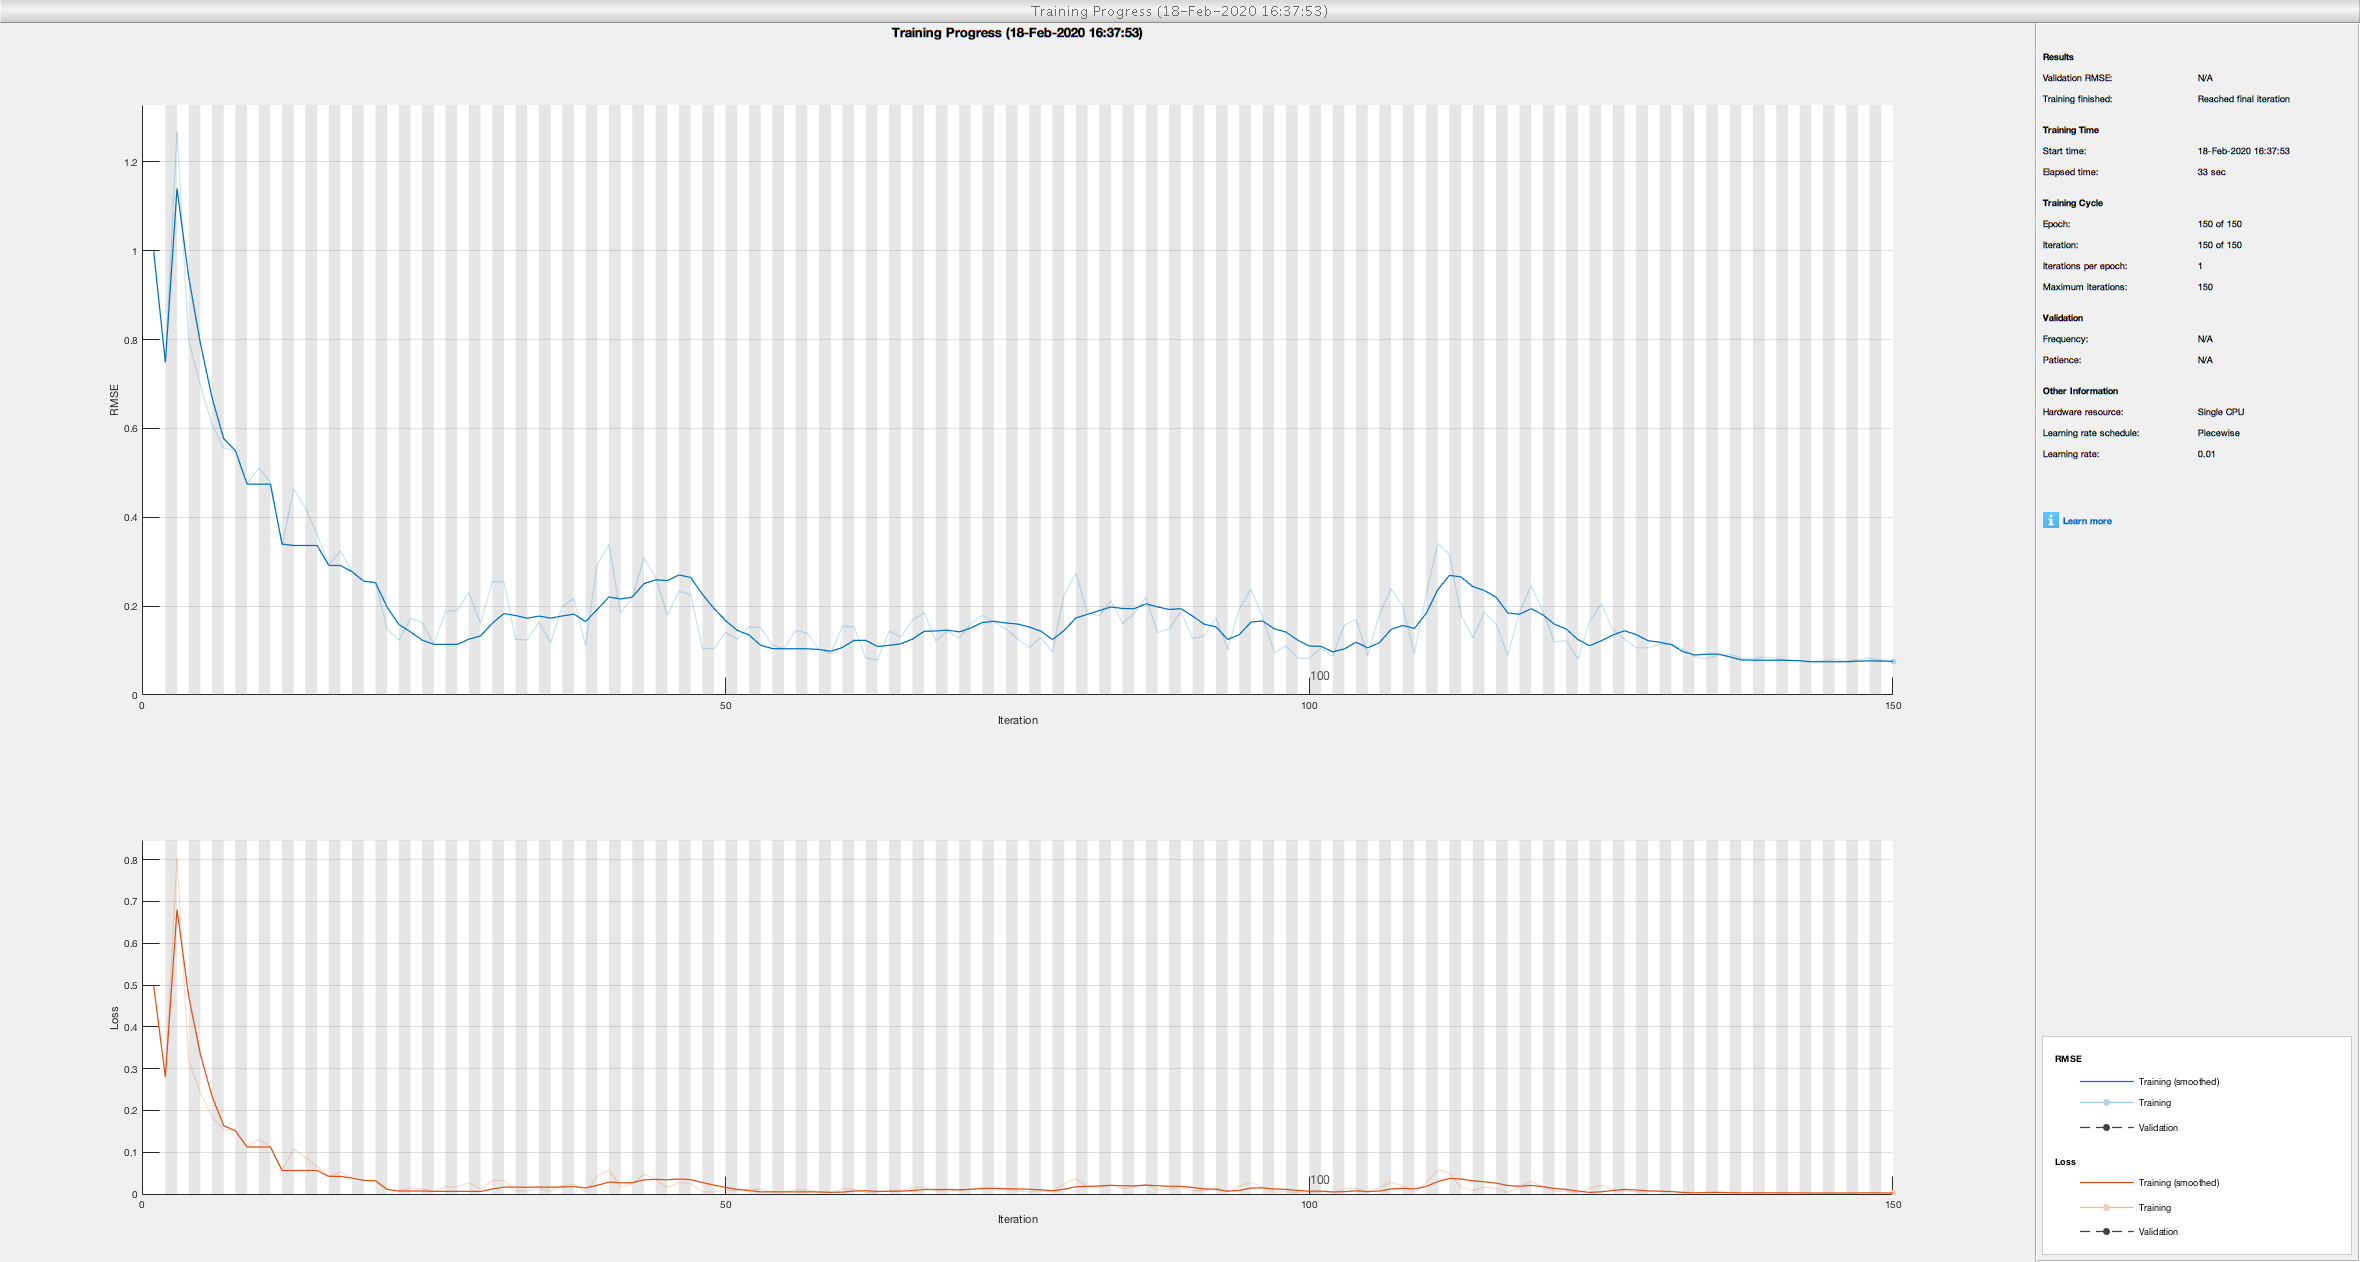

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         1.00 |          0.5 |          0.0500 |
|      50 |          50 |       00:00:12 |         0.14 |      1.0e-02 |          0.0500 |
|     100 |         100 |       00:00:23 |         0.08 |      3.4e-03 |          0.0500 |
|     150 |         150 |       00:00:33 |         0.07 |      2.8e-03 |          0.0100 |
|========================================================================================|



numTimeStepsTrain = floor(0.984*numel(data));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);
mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 55; 

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
    options = trainingOptions('adam',...
    'MiniBatchSize',1,...
    'MaxEpochs',150, ...
   'GradientThreshold',1, ...
    'InitialLearnRate',0.05, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',1, ...
   'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
2.1278e+03


net = resetState(net);
net = predictAndUpdateState(net,XTrain);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2))

rmse = 225.2191

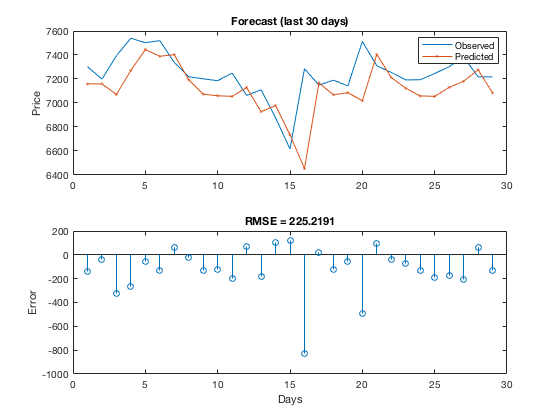

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Price")
title("Forecast (last 30 days)")
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)

YTest(29)

ans = 7218

YPred(29)

ans = 7.0845e+03

YPred(29)/YTest(29)

ans = 0.9815